# Car Suspension Project:

In this project, you'll analyze experimental data to quantify the ride quality of a car suspension. Ride quality is a term commonly used to describe how comfortable it is to ride in a vehicle.  

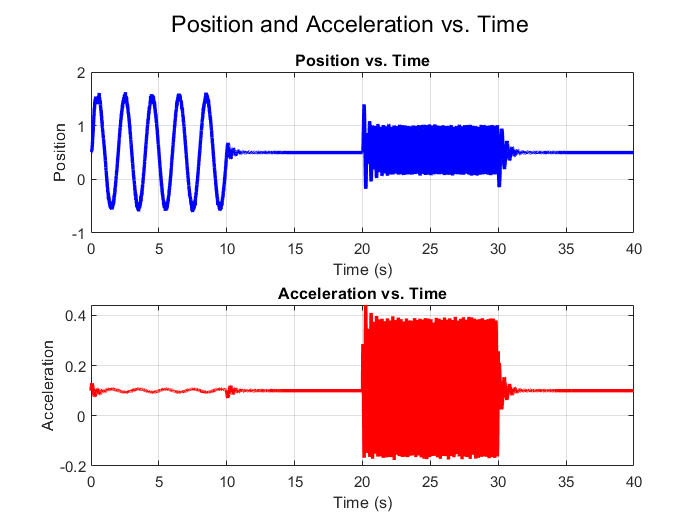

load('Suspension.mat');

% Inspect the time vector in the Variable Editor to find the sampling period
sampling_period = mean(diff(time));

figure;

% Plot the position data (low-frequency)
subplot(2,1,1);  % Create the first subplot
plot(time, Vpos, 'b', 'LineWidth', 2);  % Blue line for position
title('Position vs. Time');
xlabel('Time (s)');
ylabel('Position');
grid on;

% Plot the acceleration data (high-frequency)
subplot(2,1,2);  % Create the second subplot
plot(time, Vacc, 'r', 'LineWidth', 2);  % Red line for acceleration
title('Acceleration vs. Time');
xlabel('Time (s)');
ylabel('Acceleration');
grid on;

% Adjust the figure and subplots
sgtitle('Position and Acceleration vs. Time');  % Overall title for the figure
linkaxes([subplot(2,1,1), subplot(2,1,2)], 'x');  % Link the x-axes for synchronization

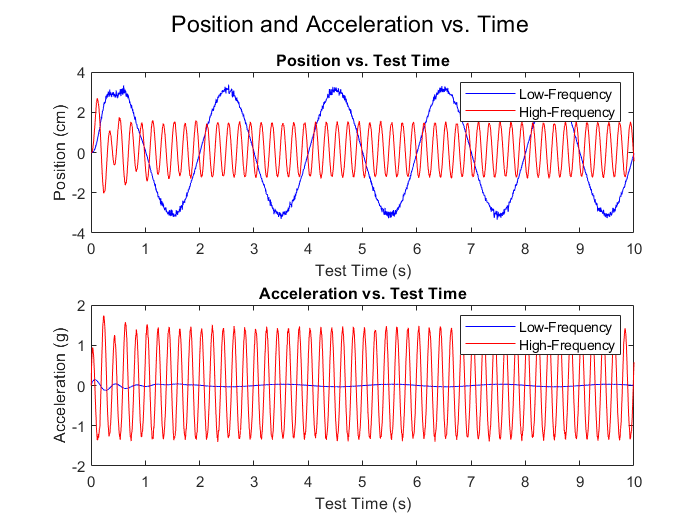

%Convert the Vpos and Vacc sensor voltages into position and acceleration vectors 
% using the respective calibration equations
pos = 3.00 * (Vpos - 0.5);
acc = 5.09 * (Vacc - 0.1);

% Define the indices for low and high-frequency tests
low_freq_indices = 1:2001;         % Low-frequency motion (0.5 Hz)
high_freq_indices = 4001:6001;     % High-frequency motion (5 Hz)

%xtract the low and high-frequency position and acceleration test data into new vectors
posLow = pos(low_freq_indices);
posHigh = pos(high_freq_indices);
accLow = acc(low_freq_indices);
accHigh = acc(high_freq_indices);

% Create a test time vector
testTime = 0:sampling_period:10;
testTime = testTime(1:length(posLow));  % Ensure the same size

% Position vs. Test Time
subplot(2,1,1);
plot(testTime, posLow, 'b', 'DisplayName', 'Low-Frequency');
hold on;
plot(testTime, posHigh, 'r', 'DisplayName', 'High-Frequency');
xlabel('Test Time (s)');
ylabel('Position (cm)');
title('Position vs. Test Time');
legend;

% Acceleration vs. Test Time
subplot(2,1,2);
plot(testTime, accLow, 'b', 'DisplayName', 'Low-Frequency');
hold on;
plot(testTime, accHigh, 'r', 'DisplayName', 'High-Frequency');
xlabel('Test Time (s)');
ylabel('Acceleration (g)');
title('Acceleration vs. Test Time');
legend;

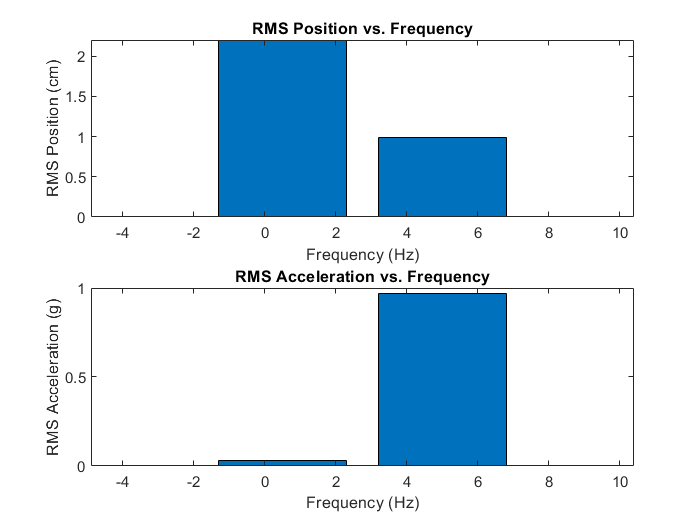

% Calculate RMS for position and acceleration vectors
posLowRMS = sqrt(mean(posLow.^2));
posHighRMS = sqrt(mean(posHigh.^2));
accLowRMS = sqrt(mean(accLow.^2));
accHighRMS = sqrt(mean(accHigh.^2));

% Create vectors for frequency, RMS position, and RMS acceleration
testFreq = [0.5, 5];  % Low and high-frequency values (0.5 and 5)
posRMS = [posLowRMS, posHighRMS];  % RMS position values
accRMS = [accLowRMS, accHighRMS];  % RMS acceleration values

% Visualize RMS position and RMS acceleration versus frequency
figure;
subplot(2,1,1);
bar(testFreq, posRMS);
xlabel('Frequency (Hz)');
ylabel('RMS Position (cm)');
title('RMS Position vs. Frequency');

subplot(2,1,2);
bar(testFreq, accRMS);
xlabel('Frequency (Hz)');
ylabel('RMS Acceleration (g)');
title('RMS Acceleration vs. Frequency');